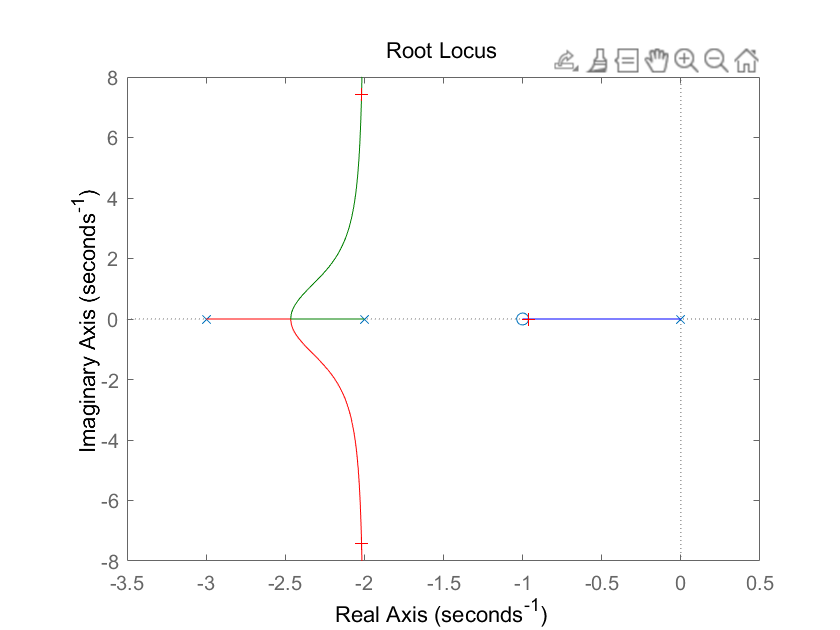

Select a point in the graphics window


selected_point = -2.0055 + 7.4215i

ans = 57.0429

clear
p = [1 1];
q = [1 5 6 0];
sys = tf(p,q);
rlocus(sys)
[r,k] = rlocus(sys);
rlocfind(sys)

clear
K = 57.0429;
num = K*[1 4 3];
den = [1 5 6+K K 0];
[r,p,k] = residue(num,den)

r =   -1.4618 - 3.4406i
  -1.4618 + 3.4406i
  -0.0764 + 0.0000i
   3.0000 + 0.0000i


p =   -2.0178 + 7.4216i
  -2.0178 - 7.4216i
  -0.9644 + 0.0000i
   0.0000 + 0.0000i



k =

     []



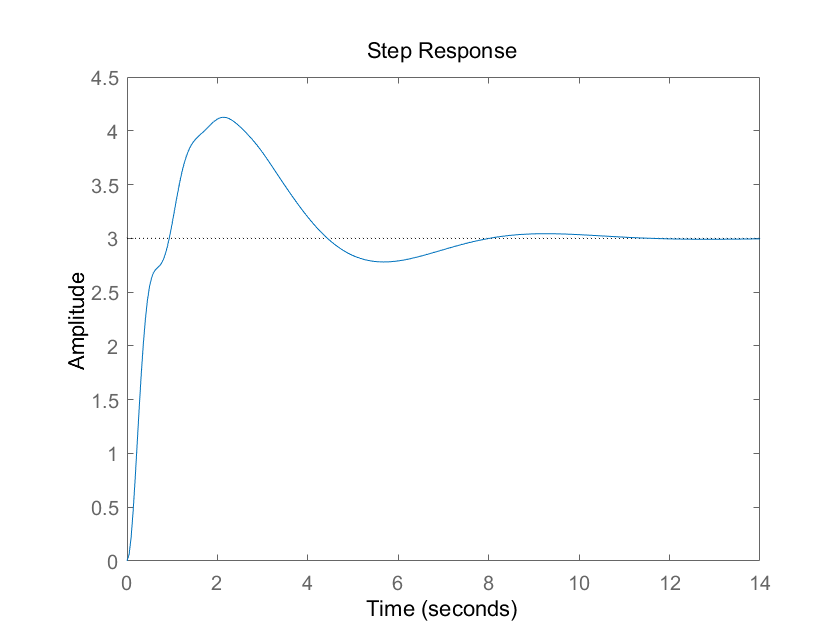

clear
K = 57.0429;
num = K*[1 4 3];
den = [1 5 6+K K K];
sys = tf(num,den);
step(sys)